# Tutorial 3: Running Inverse Kinematics in CASPR

Inverse kinematics for cable-driven robots (CDRs) refer to the determination of cable lengths for a given robot pose. 

This tutorial shows how to run inverse kinematics through two approaches:

- InverseKinematicsSimulator

- Writing your own time loop

clear;

## Load the robot and trajectory (required for both approaches)

Load a robot as shown in `T1_load_robot.mlx `and` T2_load_trajectory.mlx`

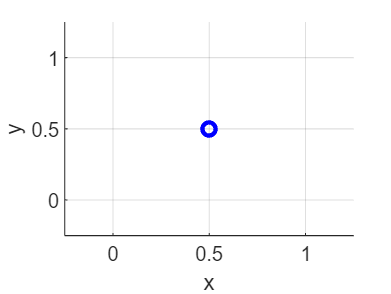

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

## 1) Solve using the InverseKinematicsSimulator

The `InverseKinematicsSimulator` provides the simplest way to run a "standard" inverse kinematics simulation for a defined trajectory. 

First, create the simulator object using the robot model

ik_sim = InverseKinematicsSimulator(cdpr_model);

Next, run the simulator on a particular trajectory

ik_sim.run(trajectory);

[INFO] Begin inverse kinematics simulator run...
[INFO] Time : 0.000000
[INFO] Time : 0.050000
[INFO] Time : 0.100000
[INFO] Time : 0.150000
[INFO] Time : 0.200000
[INFO] Time : 0.250000
[INFO] Time : 0.300000
[INFO] Time : 0.350000
[INFO] Time : 0.400000
[INFO] Time : 0.450000
[INFO] Time : 0.500000
[INFO] Time : 0.550000
[INFO] Time : 0.600000
[INFO] Time : 0.650000
[INFO] Time : 0.700000
[INFO] Time : 0.750000
[INFO] Time : 0.800000
[INFO] Time : 0.850000
[INFO] Time : 0.900000
[INFO] Time : 0.950000
[INFO] Time : 1.000000
[INFO] Time : 1.050000
[INFO] Time : 1.100000
[INFO] Time : 1.150000
[INFO] Time : 1.200000
[INFO] Time : 1.250000
[INFO] Time : 1.300000
[INFO] Time : 1.350000
[INFO] Time : 1.400000
[INFO] Time : 1.450000
[INFO] Time : 1.500000
[INFO] Time : 1.550000
[INFO] Time : 1.600000
[INFO] Time : 1.650000
[INFO] Time : 1.700000
[INFO] Time : 1.750000
[INFO] Time : 1.800000
[INFO] Time : 1.850000
[INFO] Time : 1.900000
[INFO] Time : 1.950000
[INFO] Time : 2.000000
[INFO] T

Finally, the simulator can plot the results, such as the cable lengths:

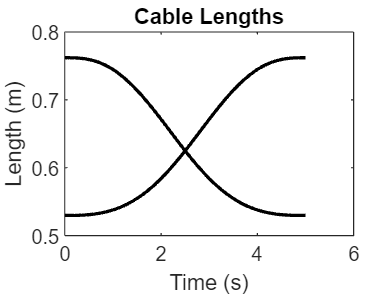

ik_sim.plotCableLengths();

Or the velocity of the cable lengths:

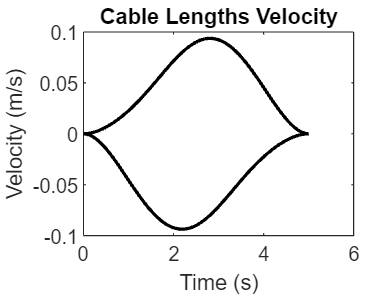

ik_sim.plotCableLengthsVelocity();

It can also plot the joint space information (like trajectories):

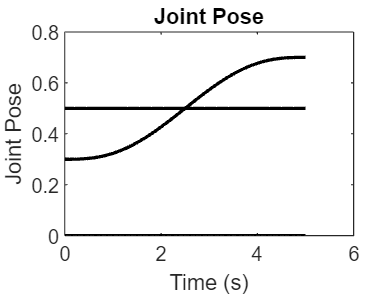

ik_sim.plotJointPose();

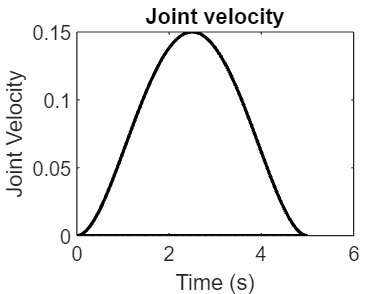

ik_sim.plotJointVelocity();

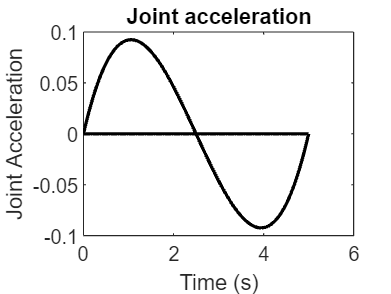

ik_sim.plotJointAcceleration();

And even the position, velocity and acceleration of the centre of gravity (CoG):

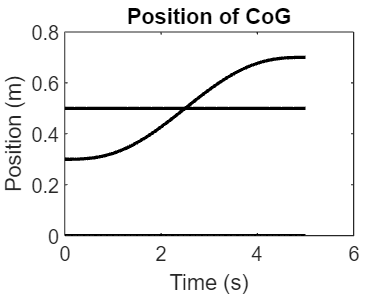

ik_sim.plotBodyCoG();

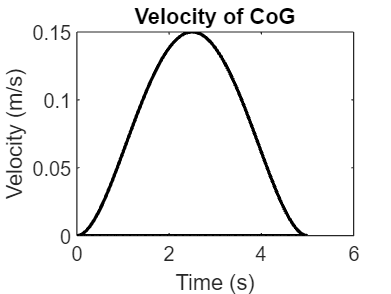

ik_sim.plotBodyCoGVelocity();

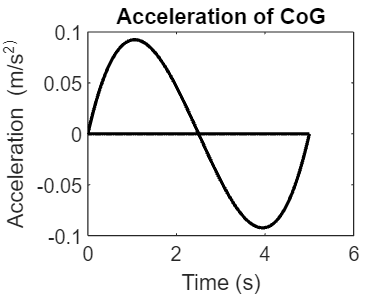

ik_sim.plotBodyCoGAcceleration();

## 2) Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop to perform the inverse kinematics. The following simple example is basically what happens within the `InverseKinematicsSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

ik_lengths = zeros(cdpr_model.numCables, length(trajectory.timeVector)); % Each column is the solution at each time step
ik_lengths_vel = zeros(cdpr_model.numCables, length(trajectory.timeVector));

Next, loop through the trajectory as a function of time:

for t = 1:length(trajectory.timeVector)

The main step within the time loop is to update the model using the joint trajectory's pose, velocity and acceleration at this time instance (and assuming the external wrench is zero)

    cdpr_model.update(trajectory.q{t}, trajectory.q_dot{t}, trajectory.q_ddot{t}, zeros(cdpr_model.numDofs, 1));

Note that in addition to using `JointTrajectory` objects, any value of `q, q_dot, q_ddot, w_ext` (joint pose, joint velocity, joint acceleration and external wrench, respectively) can be defined as input to` cdpr_model.update(q, q_dot, q_ddot, w_ext)`.

Next, the model information, including the cable lengths and cable lengths velocity, are automatically updated and hence can be stored.

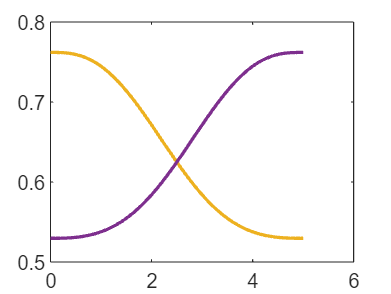

    ik_lengths(:,t) = cdpr_model.cableLengths;

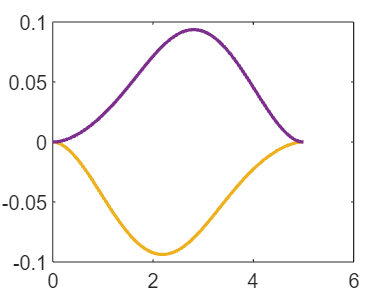

    ik_lengths_vel(:,t) = cdpr_model.cableLengthsDot;
end

The results can be plotted the way you desire yourself.

figure; 
plot(trajectory.timeVector, ik_lengths, 'LineWidth', 1.5);
figure; 
plot(trajectory.timeVector, ik_lengths_vel, 'LineWidth', 1.5);